clear
realId = 2; 

% Se till att du är i "/GitHub/TNM034_Projekt" när du läser in 
%image = imread("./Faces/db1_" + realId + ".jpg");
%image = imread("./Faces/db0_" + realId + ".jpg");
%image = imread("./Faces/DB2/il_" + realId + ".jpg");
%image = imread("./Faces/DB2/cl_" + realId + ".jpg");
%image = imread("./Faces/DB2/ex_" + realId + ".jpg");
image = imread("./Faces/DB2/bl_" + realId + ".jpg");

image = im2double(image);
imshow(image)
id = tnm034(image)

if id == realId
    fprintf('Correct id!')
else
    fprintf('Not correct id :/')
end   


## Tetst All Images

%clear all
% Load face images from a folder
imageDir = 'Faces/';
imageDir2 = 'Faces/DB2/';
testimages = dir(fullfile(imageDir, '*.jpg'));
testimages2 = dir(fullfile(imageDir2, '*.jpg'));
allImages = [testimages; testimages2];
numImages = numel(allImages);

% Read images into a cell array
faceData = cell(1, numImages);
classIds = zeros(1, numImages);
for i = 1:numImages
    % Load your image
    image = im2double(imread(fullfile(allImages(i).folder, allImages(i).name)));
    %imshow(image)
    id = tnm034(image)
    fprintf('Correct id: %i',number(allImages(i).name));
    pause(0.1)
end


## DB0

possitiveDB0 = 0;
falsePossitiveDB0 = 0;
crashDB0 = 0;
countDB0 = 0;
imageDir = 'Faces/';
for i = 1:4
    countDB0 = countDB0 + 1;
    img = imread(fullfile(imageDir, "db0_" + i + ".jpg"));
    id = tnm034(img)
    if(id == 0)
        possitiveDB0 = possitiveDB0 + 1;
    elseif(id == -1)
            crashDB0 = crashDB0 + 1;
    else
        falsePossitiveDB0 = falsePossitiveDB0 + 1;
    end
end


## DB0 Transfomred

possitiveDB0T = 0;
falsePossitiveDB0T = 0;
crashDB0T = 0;
countDB0T = 0;
imageDir = 'Faces/';
for i = 1:4
    img = imread(fullfile(imageDir, "db0_" + i + ".jpg"));
    for j = 1:5
    countDB0T = countDB0T + 1;
    imgT = randomTransform(img, [-5 5], [.9 1.1], [1 1]);
    id = tnm034(imgT)
    if(id == 0)
        possitiveDB0T = possitiveDB0T + 1;
    elseif(id == -1)
            crashDB0T = crashDB0T + 1;
    else
        falsePossitiveDB0T = falsePossitiveDB0T + 1;
    end
    end
end

## DB1

possitiveDB1 = 0;
falsePossitiveDB1 = 0;
crashDB1 = 0;
countDB1 = 0;
imageDir = 'Faces/';
for i = 1:16
    countDB1 = countDB1 + 1;
    img = imread(fullfile(imageDir, "db1_" + i + ".jpg"));
    id = tnm034(img)
    if(id == i)
        possitiveDB1 = possitiveDB1 + 1;
    elseif(id == -1)
            crashDB1 = crashDB1 + 1;
    elseif(id ~= 0)
        falsePossitiveDB1 = falsePossitiveDB1 + 1;
    end
end

## DB1 Transfomred

possitiveDB1T = 0;
falsePossitiveDB1T = 0;
crashDB1T = 0;
countDB1T = 0;
imageDir = 'Faces/';
for i = 1:16
    img = imread(fullfile(imageDir, "db1_" + i + ".jpg"));
    for j = 1:5
    countDB1T = countDB1T + 1;
    imgT = randomTransform(img, [-5 5], [.9 1.1], [0.7 1.3]);
    %imshow(imgT);
    id = tnm034(imgT)
    if(id == i)
        possitiveDB1T = possitiveDB1T + 1;
    elseif(id == -1)
            crashDB1T = crashDB1T + 1;
    elseif(id ~= 0)
        falsePossitiveDB1T = falsePossitiveDB1T + 1;
    end
    pause(1)
    end
end

## DB2

possitiveDB2 = 0;
falsePossitiveDB2 = 0;
crashDB2 = 0;
countDB2 = 0;
imageDir = 'Faces/DB2/';
imagesDB2 = dir(fullfile(imageDir, '*.jpg'));
numImages = numel(imagesDB2);

for i = 1:numImages
    % Load your image
    img = im2double(imread(fullfile(imagesDB2(i).folder, imagesDB2(i).name)));
    countDB2 = countDB2 + 1;
    id = tnm034(img)
    if(id == number(imagesDB2(i).name))
        possitiveDB2 = possitiveDB2 + 1;
    elseif(id == -1)
            crashDB2 = crashDB2 + 1;
    elseif(id ~= 0)
        falsePossitiveDB2 = falsePossitiveDB2 + 1;
    end
end


## DB2 Transfomred

pixels = 55471

min dist: 7826.696

Closest id: 8; 

id = 0

pixels = 55471

min dist: 6953.412

Closest id: 1; 

id = 1

pixels = 55471

min dist: 6233.538

Closest id: 1; 

id = 1

pixels = 55471

min dist: 7898.961

Closest id: 1; 

id = 0

pixels = 55471

min dist: 6533.809

Closest id: 1; 

id = 1

pixels = 55471

min dist: 6545.898

Closest id: 10; 

id = 10

pixels = 55471

min dist: 6946.035

Closest id: 10; 

id = 10

pixels = 55471

min dist: 5202.384

Closest id: 10; 

id = 10

pixels = 55471

min dist: 5133.023

Closest id: 10; 

id = 10

pixels = 55471

min dist: 5553.679

Closest id: 10; 

id = 10

pixels = 55471

min dist: 5676.137

Closest id: 13; 

id = 13

pixels = 55471

min dist: 4988.852

Closest id: 13; 

id = 13

pixels = 55471

min dist: 10242.142

Closest id: 5; 

id = 0

pixels = 55471

min dist: 5295.321

Closest id: 13; 

id = 13

pixels = 55471

min dist: 5764.397

Closest id: 13; 

id = 13

pixels = 55471

min dist: 7988.330

Closest id: 15; 

id = 0

pixels = 55471

min dist: 10242.142

Closest id: 5; 

id = 0

pixels = 55471

min dist: 4816.880

Closest id: 14; 

id = 14

pixels = 55471

min dist: 7489.095

Closest id: 15; 

id = 0

pixels = 55471

min dist: 7888.684

Closest id: 6; 

id = 0

pixels = 55471

min dist: 8225.073

Closest id: 2; 

id = 0

pixels = 55471

min dist: 7263.496

Closest id: 2; 

id = 0

pixels = 55471

min dist: 8360.127

Closest id: 13; 

id = 0

pixels = 55471

min dist: 6230.135

Closest id: 2; 

id = 2

pixels = 55471

min dist: 8747.754

Closest id: 13; 

id = 0

pixels = 55471

min dist: 5277.164

Closest id: 4; 

id = 4

pixels = 55471

min dist: 6112.933

Closest id: 4; 

id = 4

pixels = 55471

min dist: 6390.615

Closest id: 4; 

id = 4

pixels = 55471

min dist: 5445.918

Closest id: 4; 

id = 4

pixels = 55471

min dist: 6165.989

Closest id: 4; 

id = 4

pixels = 55471

min dist: 6016.364

Closest id: 5; 

id = 5

pixels = 55471

min dist: 7507.202

Closest id: 6; 

id = 0

pixels = 55471

min dist: 7517.876

Closest id: 6; 

id = 0

pixels = 55471

min dist: 7479.586

Closest id: 6; 

id = 0

pixels = 55471

min dist: 5240.713

Closest id: 5; 

id = 5

pixels = 55471

min dist: 6610.003

Closest id: 6; 

id = 6

pixels = 55471

min dist: 9075.285

Closest id: 6; 

id = 0

pixels = 55471

min dist: 9492.867

Closest id: 5; 

id = 0

pixels = 55471

min dist: 9396.079

Closest id: 5; 

id = 0

pixels = 55471

min dist: 9447.900

Closest id: 5; 

id = 0

pixels = 55471

min dist: 6783.190

Closest id: 7; 

id = 7

pixels = 55471

min dist: 9471.982

Closest id: 7; 

id = 0

pixels = 55471

min dist: 9487.824

Closest id: 7; 

id = 0

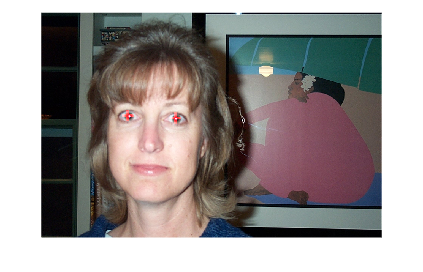

pixels = 55471

min dist: 5006.390

Closest id: 7; 

id = 7

Arrays have incompatible sizes for this operation.

Error in findEyes (line 47)
    filt = map.* mask;

Error in tnm034 (line 12)
    [eye1,eye2] = findEyes(im);

Related documentation

possitiveDB2T = 0;
falsePossitiveDB2T = 0;
crashDB2T = 0;
countDB2T = 0;
imageDir = 'Faces/DB2/';
imagesDB2 = dir(fullfile(imageDir, '*.jpg'));
numImages = numel(imagesDB2);

for i = 1:numImages
    % Load your image
    img = im2double(imread(fullfile(imagesDB2(i).folder, imagesDB2(i).name)));
    for j = 1:5
    countDB2T = countDB2T + 1;
    imgT = randomTransform(img, [-5 5], [.9 1.1], [1 1]);
    id = tnm034(imgT)
    if(id == number(imagesDB2(i).name))
        possitiveDB2T = possitiveDB2T + 1;
    elseif(id == -1)
            crashDB2T = crashDB2T + 1;
    elseif(id ~= 0)
        falsePossitiveDB2T = falsePossitiveDB2T + 1;
    end
    end
end

## DB2 Transfomred corr

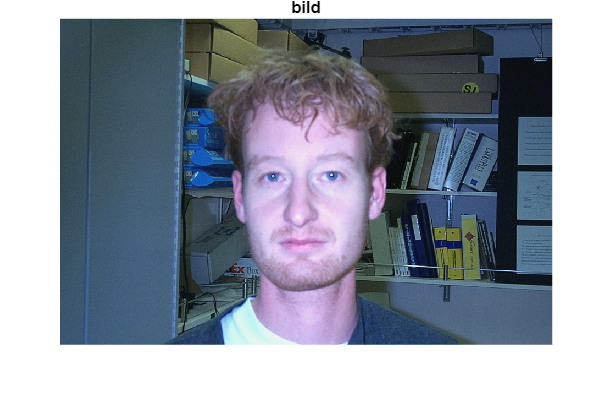

possitiveDB2T = 0;
falsePossitiveDB2T = 0;
crashDB2T = 0;
countDB2T = 0;
imageDir = 'Faces/DB2/';
imagesDB2 = dir(fullfile(imageDir, '*.jpg'));
numImages = numel(imagesDB2);

for i = 1:numImages
    % Load your image
    img = im2double(imread(fullfile(imagesDB2(i).folder, imagesDB2(i).name)));
    for j = 1:5
    imgT = randomTransform(img, [-5 5], [.9 1.1], [.7 1.3]);
    imgT = contrastStretchColor((colorCorrection(imgT)),0,1);
    imshow(imgT); title('bild')

    end
end